# Dynamix

clear all
addpath('.\lib')

## System Definition

% First, we must construct a system to operate on and visualize it
% Intra-vertebrae characteristics
theta = 2*pi/3;
r = 1;

% Number of Vertebrae
n_v = 8;
% Vertebrae overlap
b = 1.5;
% Rotation about own center
alpha = 0;
% Rotation wrt prev. vertebrae
phi = 7;

[N, C, C_B, C_S, M, M_B, M_S] = sys_def(r, theta, n_v, b, phi, alpha);

R = zeros(3, n_v);
B = zeros(3, n_v * 3);
el = 0;
for i = 3:3:3*n_v
    node_1 = N(:,i-2);
    node_2 = N(:,i-1);
    node_3 = N(:,i);
    
    ctr = [
        mean(N(1, i-2:i));
        mean(N(2, i-2:i));
        mean(N(3, i-2:i));
    ];
    R(:,i/3) = ctr;
    B(:,i - 2) = node_1 - ctr;
    el = norm(B(:,i - 2));

    rotation = rotate_abt_point(ctr(1), ctr(2), 120);
    B(:,i - 1) = rotation * B(:,i - 2);
    B(:,i) = rotation * B(:,i - 1);
end
Q = [R B];


% Then the PSI matrix needs to be constructed to satisfy:
% N = Q * Psi + Y
% Psi matrix is main conversion, then 0s for all parts that are fixed
% Y matrix contains all the points that are fixed 

Y = [zeros(3, 3*(n_v))];


% Constructing Psi matrix
% Top portion skips fixed nodes and selects r vectors
psi_top = [];
for i = 1:n_v
    psi_top = [psi_top, ones_row(n_v, 3, i)];
end

% psi_middle = zeros(3, 3*n_v);
psi_bottom = el * [eye(3*(n_v))];
psi = [psi_top;psi_bottom]';

inversion_error = N - (Q * psi' + Y);


% Set physical properties of the bars
m = 1;                    %mass
t_mu = 0.2;      
mu = 0.3;       
J_tot = (1/4)*m*el^2;       %moment of inertia
J = J_tot/3;
M = diag([m,m,J,J,J,J,J,J]);
W = zeros(3, 3*n_v);
t_span = 0:0.001:20;
ol_f = 2;
ol_phase = 18;
ol_mag = .14;
% ol_mag = 0;
base_gamma = 1/2 * [20 20 10 10];


## ODE Solver

% Initial state
gamma = diag(repmat(base_gamma, 1, (n_v-1)));
B_tru = zeros(3, n_v);
for v = 1:n_v
    B_tru(:,v) = B(:,(3*v)-2);
end
state_0 = [R B_tru zeros(3, 2*n_v)];
state_0 = reshape(state_0, [], 1);
state_0(6*n_v+1:end);

options = odeset('RelTol',1e-13,'AbsTol',1e-13,'Refine',10);
odefun = @(t,state)[dynamix(t, state, W, psi, C_S, Y, gamma, J, m, t_mu, mu, ol_f, ol_phase, ol_mag, @cos)];

[t,sol] = ode45(odefun,t_span,state_0,options);

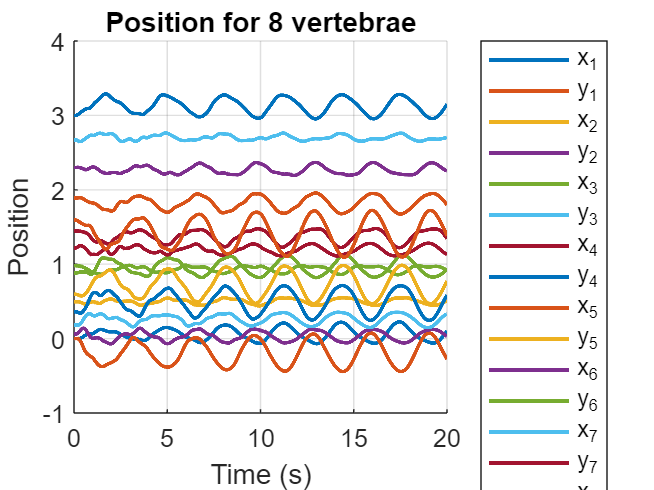

figure
legend_entries = cell(2*n_v,1);
hold on
for v = 1:n_v
    plot(t, sol(:,3*(v-1)+1), t, sol(:,3*(v-1)+2),'linew',1.5)
    legend_entries{2*(v-1)+1} = "x_"+num2str(v);
    legend_entries{2*(v-1)+2} = "y_"+num2str(v);
end
hold off
legend(legend_entries,'Location','eastoutside')
title("Position for " + num2str(n_v) + " vertebrae")
grid on;
xlabel('Time (s)')
ylabel('Position')

% figure(4)
% plot(t,sol(:,10:11),t,sol(:,13:14),t,sol(:,16:17),'linew',1.5)
% legend('$b_{3x}$','$b_{3y}$','$b_{6x}$','$b_{6y}$','$b_{9x}$','$b_{9y}$','interpreter','latex','location','eastoutside');
% title("Orientation vectors for both spines")
% grid on;
% xlabel('Time (s)')
% ylabel('unitless')
% set(gcf,'Color','w')
% set(gca,'FontSize',14)
% set(gca,'FontName','ComputerModern')
% set(gca, 'box', 'off')
% % axis([tspan(1) tspan(end) -0.2 1.2])


## Animation

set(0,'DefaultFigureVisible','off')

animation_sample = 150;

mov(1:length(1:animation_sample:size(sol,1))) = struct('cdata', [], 'colormap', []);
num_frames = length(1:animation_sample:size(sol,1))

num_frames = 134


index = 1;
for i = 1:animation_sample:size(sol,1)
    
    state_step = sol(i,:);
    % Reshape state vector to recover structure
    state = reshape(state_step, 3, 4 * n_v);
    
    % The Q matrix needs to be reconstructed from the state
    R = zeros([3, n_v]);
    B = zeros([3, n_v * 3]);
    R_dot = R;
    B_dot = B;
    for v = 1:n_v
        R(:,v) = state(:,v);
    
        R_dot(:,v) = state(:, n_v*2 + v);
    
        B(:,(3*v)-2) = state(:,n_v + v);
        B(:,(3*v)-1) = rotz(120) * state(:,n_v + v);
        B(:,(3*v)-0) = rotz(-120) * state(:,n_v + v);
    
        B_dot(:,(3*v)-2) = state(:,n_v*3 + v);
        B_dot(:,(3*v)-1) = rotz(120) * state(:,n_v*3 + v);
        B_dot(:,(3*v)-0) = rotz(-120) * state(:,n_v*3 + v);
    end
    Q = [R B];
    Q_dot = [R_dot B_dot];

    N = Q * psi' + Y;
    curr_frame = graph_sys(N, n_v);
    mov(index) = getframe(curr_frame);
    index = index+1;

end

% Create VideoWriter object
writerObj = VideoWriter('animation.avi');

% Set frame rate (optional)
movie_length = max(t_span)

movie_length = 20


writerObj.FrameRate = length(mov) / movie_length % Adjust the frame rate as needed

writerObj =   VideoWriter

    General Properties:

       Filename:                 'animation.avi'
       Path:                     'C:\Users\pow3r\Code\Lab\dyn_analysis'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                6.7
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods



% Open the video writer
open(writerObj);

% Write each frame to the video
for id = 1:length(mov)
    writeVideo(writerObj, mov(id).cdata);
end

% Close the video writer
close(writerObj);

function RTR = rotate_abt_point(tx, ty, theta)
    ROT = rotz(theta);
    RTR = lintr(tx, ty) * ROT * lintr(-tx, -ty);
end

function TR = lintr(tx, ty)
    TR = [1 0 tx; 0 1 ty; 0 0 1];
end